## 导入数据

clear;
data=readmatrix('all_data_first.xlsx')

data =    77.9200   72.6100   87.9000
   83.7300   77.9300   90.6500
   76.8300   71.5000   90.3800
   80.3600   74.0600   93.4600
   77.4200   68.7500   86.4000
   75.4300   59.8900   86.6800
   75.0200   67.4300   89.9400
   83.0400   76.5200   95.2300
   85.8200   81.0900   91.4700
   87.9100   86.4700   95.6200


## 数据样式

绘制折线图

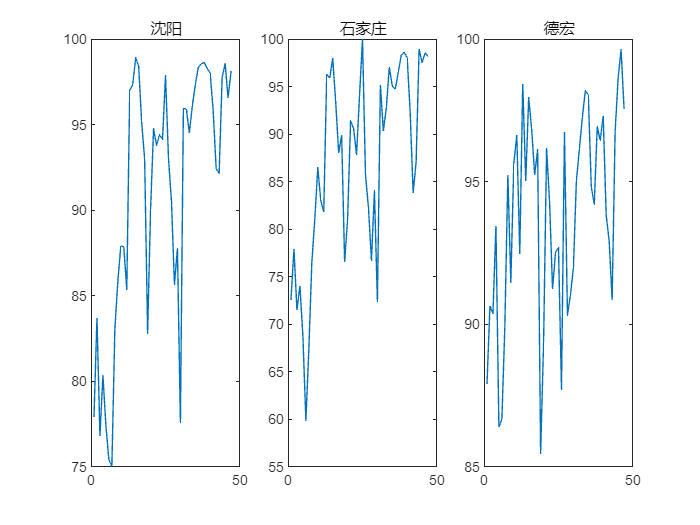

figure(1)
tit={'沈阳','石家庄','德宏'};
for i=1:3
    subplot(1,3,i);
    plot(data(:,i))
    title(tit(i))
end

## 异常值检验

绘制箱线图

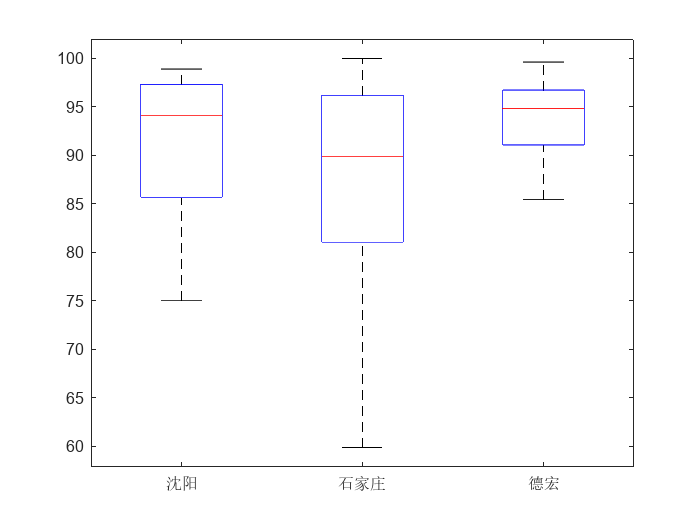

figure(2)
subplot(1,1,1)
boxplot(data,tit)

三组数据都没有异常值，若有需要剔除。因为异常值会对相关性分析的结果造成很大影响

## 分析两两变量间的线性关系

绘制散点图

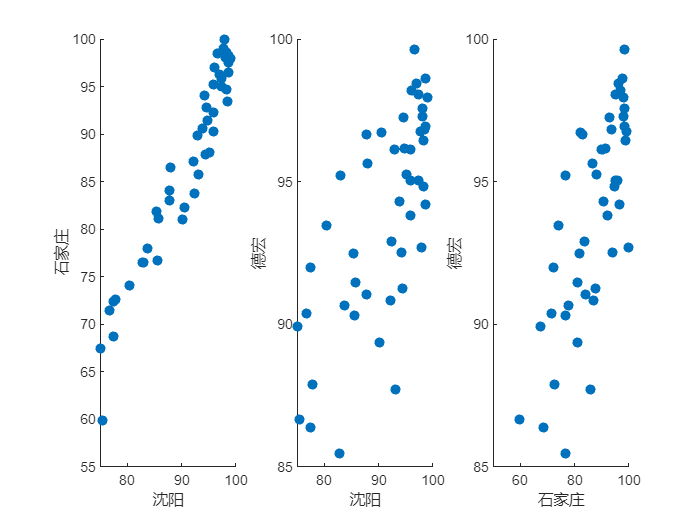

figure(3)

subplot(1,3,1)
scatter(data(:,1),data(:,2),"filled")
xlabel(tit(1)),ylabel(tit(2))

subplot(1,3,2)
scatter(data(:,1),data(:,3),"filled")
xlabel(tit(1)),ylabel(tit(3))

subplot(1,3,3)
scatter(data(:,2),data(:,3),"filled")
xlabel(tit(2)),ylabel(tit(3))

由此可见沈阳与石家庄的详细关系最为显著，其次为石家庄与德宏，最次为沈阳与德宏

## 正态分布检验

Kolmogorov-Smirnov检验

for k=1:3
    A=data(:,k);
    alpha=0.05;
    [mu,sigma]=normfit(A);
    p1=normcdf(A,mu,sigma);
    [H1,s1]=kstest(A,[A,p1],alpha)
    n=length(A);
    if H1==0
        disp('该数据服从正态分布。')
    end
end

H1 = logical
   0


s1 = 0.1040

该数据服从正态分布。


H1 = logical
   0


s1 = 0.5227

该数据服从正态分布。


H1 = logical
   0


s1 = 0.4877

该数据服从正态分布。


由此看来，三组数据都满足正态分布

由上面各项检验来看，数据满足皮尔逊相关性分析要求，可以使用。

## 皮尔逊相关性分析

绘制热力图

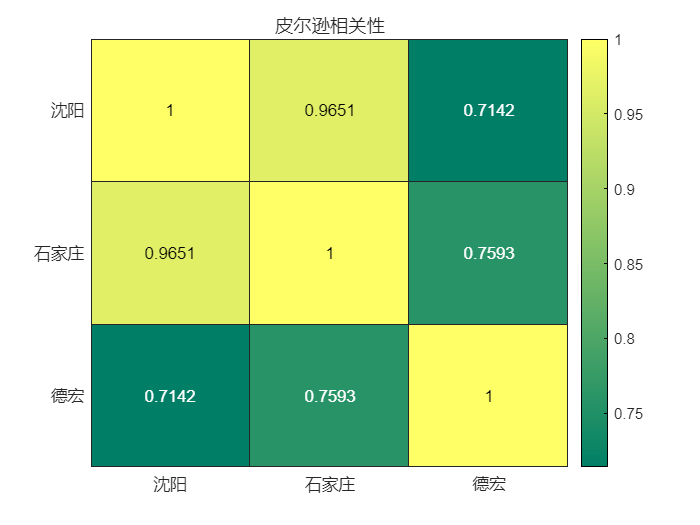

figure(4)
subplot(1,1,1)
% 求维度之间的相关系数
rho = corr(data, 'type','pearson');
% 绘制热图
xvalues = tit;
yvalues = tit;
h = heatmap(xvalues,yvalues, rho);
h.Title = '皮尔逊相关性';
colormap summer

很明显石家庄与沈阳的相关系数最大，为0.9651，且呈现正相关。